clc; clearvars;
addpath overlap_functions\

z = linspace(1,10e3,1e2);
r = linspace(0,6,1e3); % distance from telescope OA, change so max distance is based on telescope FOV
theta = linspace(0,2*pi,1e2);

z_km = z./1000;

[rG,zG,tG] = meshgrid(r,z,theta);

delta = 0.5;

rpG = sqrt(rG.^2 + delta^2 - 2*delta.*rG.*cos(tG)); % distance to laser axis in terms of distance to and angle about telescope axis

laser_beamwaist = 1.5e-3; % w0
laser_divergence = .5e-3; % phi0

aperture_radius = 5e-3; % a
obstruction_radius = 0; % b
za = 0; % distance between focal plane and aperture

telescope_radius = .254; % R
telescope_focus = 5; % f
telescope_fov = aperture_radius / (telescope_focus + za); % half angle

r1 = coneRadius(telescope_radius,telescope_fov,z);
r2 = laserBeamWidth(laser_beamwaist,laser_divergence,z);

Show simplified overlap function determined by overlap between laser beam cross section and telescope FOV 

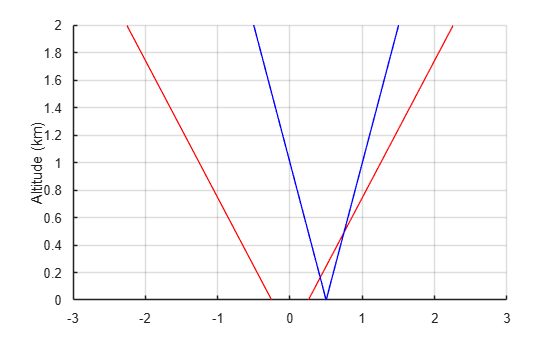

A_overlap = circleOverlap(r1,r2,repmat(delta,1,length(r1)));
O_simple = A_overlap./(pi.*r2.^2);

figure;
hold on;
plot(r1,z_km,'r')
plot(-r1,z_km,'r')

plot(delta+r2, z_km,'b')
plot(delta+-r2, z_km,'b')

hold off
ylabel("Altitude (km)")
grid on

% xlim([-.5 5])
ylim([0 2])

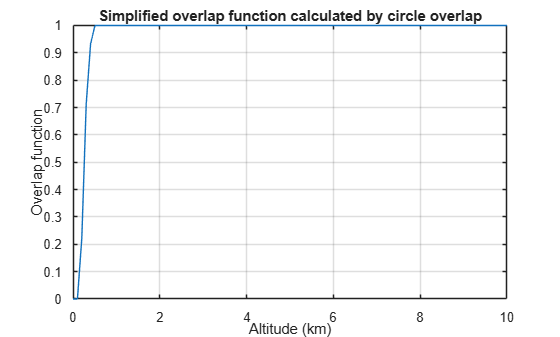

figure;
plot(z_km,O_simple);
ylabel("Overlap function")
xlabel("Altitude (km)")
title("Simplified overlap function calculated by circle overlap")
grid on

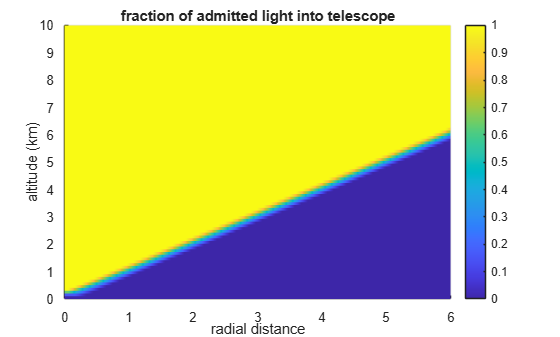

psi = overlapFrac(aperture_radius,obstruction_radius,telescope_radius,telescope_focus,r,za,z);

figure
s = surf(rG(:,:,1),zG(:,:,1)./1000,psi);
s.EdgeColor = 'none';
xlabel('radial distance')
ylabel('altitude (km)')
title('fraction of admitted light into telescope')
colorbar
clim([0 1])
view(0,90)

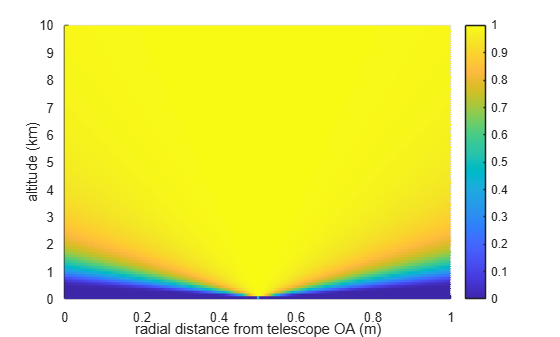

w = laserBeamWidth(laser_beamwaist,laser_divergence,zG);

P0 = 1;
f = laserProfile(w,rpG,"gaussian");
% f = laserProfile(w,rpG,"rectangular");

figure
s = surf(rG(:,:,1),zG(:,:,1)./1000,f(:,:,1));
s.EdgeColor = 'none';
xlabel('radial distance from telescope OA (m)')
ylabel('altitude (km)')
title('')
view(0,90)
colorbar
clim([0 P0])
xlim([0 1])

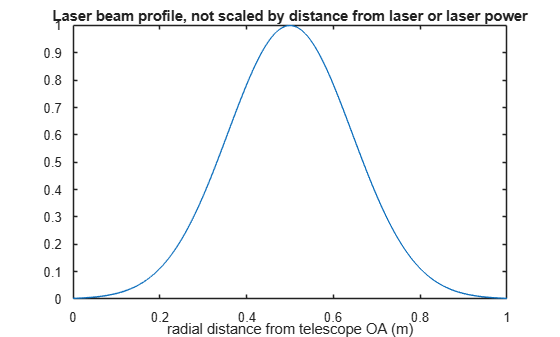

zi = 5;
figure;
plot(rG(zi,:,1),f(zi,:,1))
xlim([0 1])
xlabel("radial distance from telescope OA (m)")
% ylabel("Irradiance")
title("Laser beam profile, not scaled by distance from laser or laser power")

O_gauss = overlapFunc(z,laser_beamwaist, laser_divergence, aperture_radius, obstruction_radius, telescope_radius, telescope_focus, za, delta, "gaussian");
% O_rect = overlapFunc(z,laser_beamwaist, laser_divergence, aperture_radius, obstruction_radius, telescope_radius, telescope_focus, za, delta, "rectangular");

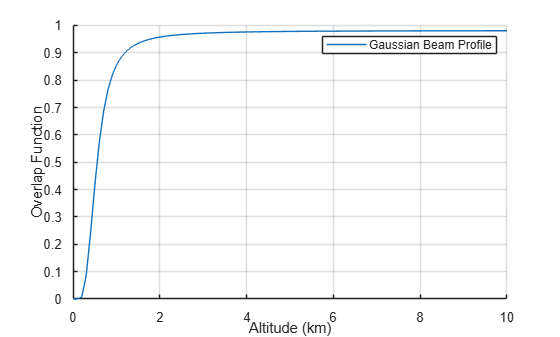

figure;
hold on
plot(z_km,O_gauss,"DisplayName","Gaussian Beam Profile")
% plot(z_km,O_rect,"DisplayName","Rectangular Beam Profile")
% plot(z_km,O_simple,"DisplayName","Simple Circle Overlap")
hold off
legend 
grid on
xlabel("Altitude (km)")
ylabel("Overlap Function")